Primeri za razdelek računanja determinante jacobijeve matrike za trikotne Coonsove ploskve.

export_images = false; % nastavi na false da se slike ne exportajo

u = linspace(0, 1, 201);

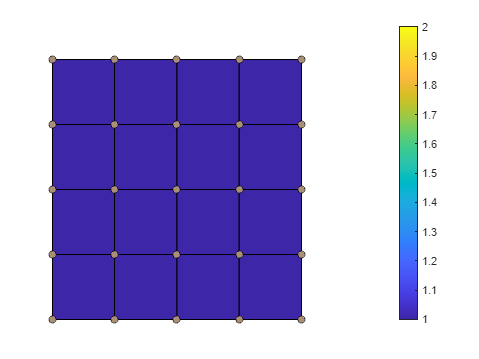

N = 5;

Bx = repmat(1:N, N, 1);
By = Bx';

[bx, by] = coons_patch(Bx, By);
[bx1, by1, ~] = bezier2(bx, by, zeros(size(bx)), u, u);

J = calculate_jacobi(bx, by, u, u);

m = max(J(:)) + 1;

figure
surf(bx1, by1, J, 'EdgeColor', 'none');
hold on
mesh(bx, by, m*ones(size(bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(bx, by, m*ones(size(bx)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])

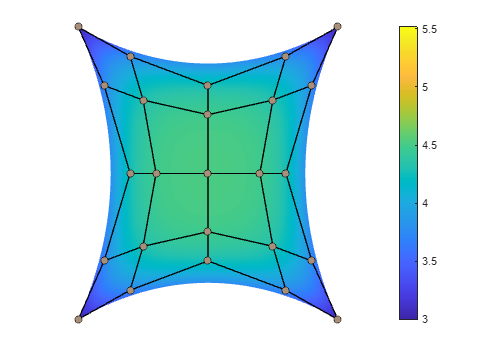

Bx = [1 3 6 9 11; 2 0 0 0 10; 3 0 0 0 9; 2 0 0 0 10; 1 3 6 9 11];
By = [1 2 3 2 1; 3 0 0 0 3; 6 0 0 0 6; 9 0 0 0 9; 11 10 9 10 11];

[bx, by] = coons_patch(Bx, By);
[bx1, by1, ~] = bezier2(bx, by, zeros(size(bx)), u, u);

J = calculate_jacobi(bx, by, u, u);

m = max(J(:)) + 1;

figure
surf(bx1, by1, J, 'EdgeColor', 'none');
hold on
mesh(bx, by, m*ones(size(bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(bx, by, m*ones(size(bx)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])

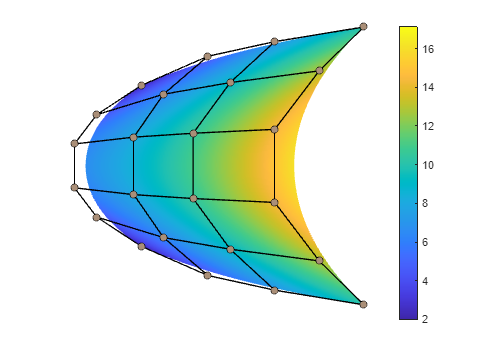

Bx = [4 7 10 14; 2 0 0 12; 1 0 0 10; 1 0 0 10; 2 0 0 12; 4 7 10 14];
By = [5 3 2 1; 7 0 0 4; 9 0 0 8; 12 0 0 13; 14 0 0 17; 16 18 19 20];

[bx, by] = coons_patch(Bx, By);
[bx1, by1, ~] = bezier2(bx, by, zeros(size(bx)), u, u);

J = calculate_jacobi(bx, by, u, u);

m = max(J(:)) + 1;

figure
surf(bx1, by1, J, 'EdgeColor', 'none');
hold on
mesh(bx, by, m*ones(size(bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(bx, by, m*ones(size(bx)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])

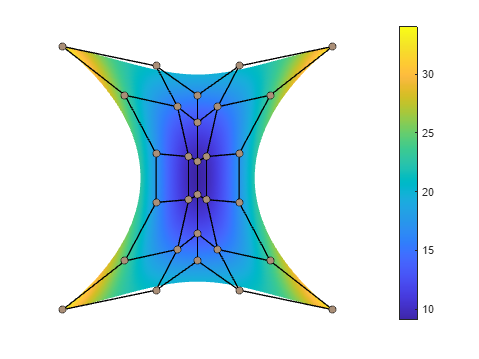

alpha = -0.2;

Bx = [1 10 14 18 27; 7 0 0 0 21; 10 0 0 0 18; 10 0 0 0 18; 7 0 0 0 21; 1 10 14 18 27];
By = [1 3 6 3 1; 6 0 0 0 6; 12 0 0 0 12; 17 0 0 0 17; 23 0 0 0 23; 28 26 23 26 28];

[bx, by] = permanence_patch(Bx, By, alpha);
[bx1, by1, ~] = bezier2(bx, by, zeros(size(bx)), u, u);

J = calculate_jacobi(bx, by, u, u);

m = max(J(:)) + 1;

figure
surf(bx1, by1, J, 'EdgeColor', 'none');
hold on
mesh(bx, by, m*ones(size(bx)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(bx, by, m*ones(size(bx)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
colorbar

grid off
set(gca,'visible','off')

view([-0.50 90.00])